ParentDir = "F:\YuLab\Work\GPS\Video";
TaskDir = uigetdir(ParentDir, "Choose animal directionory");

TrajGroupClassFile = dir(TaskDir+"\*TrajGroupClass*.mat");
if length(TrajGroupClassFile)>1
    fprintf("More than one TrajGroupClass found");
    return;
end

load(fullfile(TaskDir, TrajGroupClassFile.name));



Beh = readtable("D:\YuLab\Work\GPS\Data\Kennard\GPS_07_Kornblum1000SRTSelf\GPSProgressClass_KornblumSRT_KENNARD.csv");
Beh = Beh(ismember(Beh.Label, ["Control", "Chemo"]) & Beh.Stage==1 & Beh.Cued==0, :);

Beh.SessionDate = string(Beh.SessionDate);
Beh = addvars(Beh, mean(post_sample_zi, 2), 'NewVariableNames', "zi");

zi_Traj = zeros(height(obj.TrialInfo), 1);
c = 1;

Sessions = unique(Beh.SessionDate);
for i = 1:length(Sessions)

    TrajTrials = obj.TrialInfo(obj.TrialInfo.Session==Sessions(i), "Trial");
    ziTrials   = Beh(Beh.SessionDate==Sessions(i), "Trials");
    zi         = Beh(Beh.SessionDate==Sessions(i), "zi");

    for j = 1:length(TrajTrials.Trial)
        if ~ismember(TrajTrials.Trial(j), ziTrials.Trials)
            zi_Traj(c) = nan;
        else
            zi_Traj(c) = zi.zi(ziTrials.Trials==TrajTrials.Trial(j));
        end
        c = c+1;
    end

end


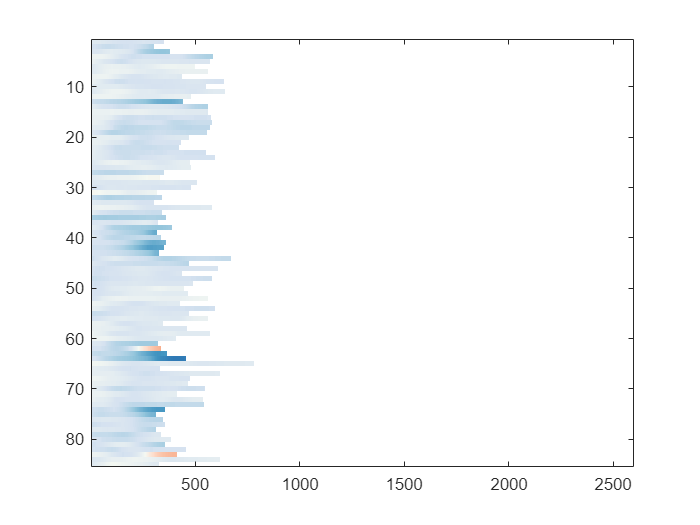

mycolormap = customcolormap_preset('red-white-blue');
figure(); colormap(mycolormap);
imagesc(obj.AngleHeadMatIn(zi_Traj<.5, :), "AlphaData", ~isnan(obj.AngleHeadMatIn(zi_Traj<.5, :)))
clim([-90 90])

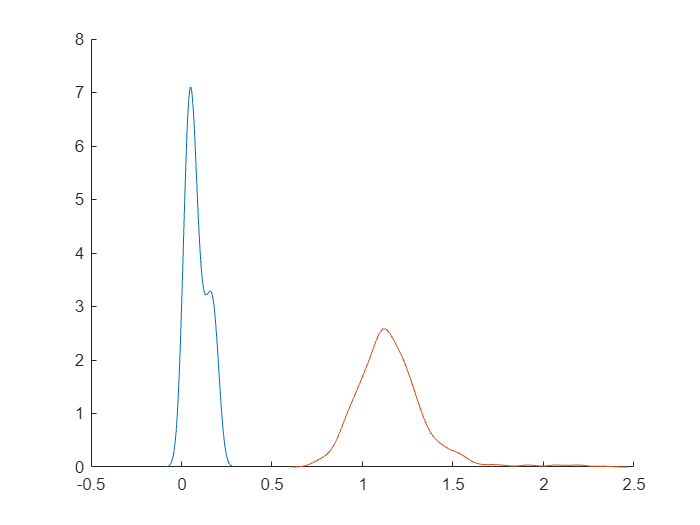


figure(); hold on
ksdensity(obj.HD(zi_Traj==0))
ksdensity(obj.HD(zi_Traj==1))

obj.TrialInfo = addvars(obj.TrialInfo, zi_Traj, 'NewVariableNames', "zi");
obj.save(TaskDir)